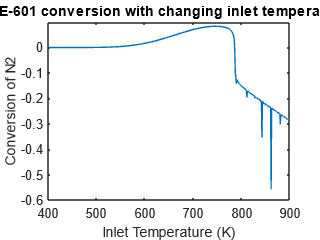


for l = 1:500
    Temp(l) = 400 + l*1;
    T(1) = Temp(l);

    for i = 2:MAXvol/dV
    
        V(i) = (i-1)*dV;
        eta(i-1) = b0+b1*T(i-1)+b2*X(i-1)+b3*(T(i-1)^2)+b4*(X(i-1)^2)+b5*(T(i-1)^3)+b6*(X(i-1)^3);
        fugnh3(i-1) = 0.1438996 +((0.2028538E-2)*T(i-1))-((0.448762E-3)*P(i-1))-((0.1142945E-5)*T(i-1)^2)+((0.2761216E-6)*P(i-1));
        fugn2(i-1) =  0.93431737 + ((0.3101804E-3)*T(i-1)) + ((0.295896E-3)*P(i-1)) - ((0.2707279E-6)*(T(i-1))^2) + (0.477507E-6*(P(i-1))^2);
        fugh2(i-1) = exp( exp(-3.8402*T(i-1)^0.125+0.541)*P(i-1) - exp(-0.1263*T(i-1)^0.5-15.98)*P(i-1)^2 + 300*exp(-0.011901*T(i-1)-5.941)*exp(P(i-1)/300));
        ynh3(i-1) = (YNH3 + 2*X(i-1)*YN2)/(1-2*X(i-1)*YN2);
        yn2(i-1) = (YN2*(1-X(i-1)))/(1-2*X(i-1)*YN2);
        yh2(i-1) = (YH2 - 3*X(i-1)*YN2)/(1-2*X(i-1)*YN2);
        yar(i-1) = YAr/(1-2*X(i-1)*YN2);
        yo2(i-1) = YO2/(1-2*X(i-1)*YN2);
        anh3(i-1) = ynh3(i-1)*fugnh3(i-1)*P(i-1);
        an2(i-1) = yn2(i-1)*fugn2(i-1)*P(i-1);
        ah2(i-1) = yh2(i-1)*fugh2(i-1)*P(i-1);
        K(i-1) = 10^(-2.691122*log10(T(i-1))-(5.519265*10^(-5))*T(i-1)+(1.848863*10^(-7))*T(i-1)^2+(2001.6/T(i-1))+2.6899);
        Kequil(i-1) = sqrt((anh3(i-1)^2)/(an2(i-1)*ah2(i-1)^3));
        Xequil(i-1) = Kequil(i-1)/(1+Kequil(i-1));
        k2(i-1) = k0*exp(-E2/(R*T(i-1)));
        Rnh3(i-1) = 2*k2(i-1)*(K(i-1)^2*an2(i-1)*((ah2(i-1)^3)/(anh3(i-1)^2))^alpha-((anh3(i-1)^2)/(ah2(i-1)^3))^(1-alpha)); %kmol/m3.hr
        dHr(i-1) = 4.184*(-(P(i-1))*(0.54526+(840.609)/(T(i-1))+(459.734E6)/(T(i-1)^3))-5.34685*T(i-1)-(0.2525E-3)*T(i-1)^2+(1.69167E-6)*T(i-1)^3-9157.09); %kJ/kmol
        CpH2(i-1) = 4.184*(6.952+((-0.04567E-2)*(T(i-1)))+((0.09563E-5)*(T(i-1))^2)+((-0.2079E-9)*(T(i-1))^3));
        CpN2(i-1) = 4.184*(6.903+((-0.03753E-2)*(T(i-1)))+((0.193E-5)*(T(i-1))^2)+((-0.6861E-9)*(T(i-1))^3));
        CpAr(i-1) = 4.184*(4.75);
        CpNH3(i-1) = 4.184*(6.5846 - T(i-1)*(0.61251E-2) + (T(i-1)^2)*(0.23663E-5)-(T(i-1)^3)*(1.5981E-9)+96.1678-0.067571*P(i-1)+T(i-1)*(-0.2225+(1.6847E-4)*(P(i-1)))+(T(i-1)^2)*((1.289E-4)-(1.0095E-7)*P(i-1)));
        Cpmix(i-1) = yh2(i-1)*CpH2(i-1) + ynh3(i-1)*CpNH3(i-1) + yn2(i-1)*CpN2(i-1) + CpAr(i-1)*yar(i-1);
        
        dG(i-1) = -dHr(i-1)*Rnh3(i-1)*V(i);
        dR(i-1) = (F0N2*CpN2(i-1) + F0NH3*CpNH3(i-1) + F0H2*CpH2(i-1) + F0Ar*CpAr(i-1))*(T(i-1)-T(1));
    
        dXdV = (eta(i-1) * Rnh3(i-1) )/(2*F0N2);
        dTdV = (-(dHr(i-1))*eta(i-1)*Rnh3(i-1))/(F0TOTAL*Cpmix(i-1));
        %dPdL = (mu*u*150*(1-void)^2)/((void^3)*(dp^2)) - (1.75*rho*(u^2)*(1-void))/((void^3)*(dp))
        X(i) = X(i-1) + dXdV*dV;
        T(i) = T(i-1) + dTdV*dV;
        %P(i) = P(i-1) + dPdL*dL
    end
    Xout(l) = X(end);
    
    Tin(l) = T(1,1);
    Tout(l) = T(1,end);
    
end

plot(Tin,Xout)
ylabel("Conversion of N2")
xlabel("Inlet Temperature (K)")
title("RE-601 conversion with changing inlet temperature")

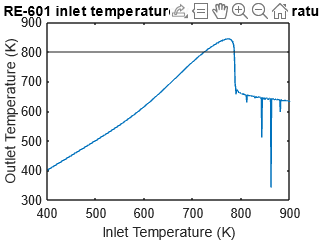




plot(Tin,Tout)
ylabel("Outlet Temperature (K)")
xlabel("Inlet Temperature (K)")
title("RE-601 inlet temperature vs outlet temperature")
yline(800)